Um aluno do primeiro ano de um curso de Engenharia tem todas as semanas 2 aulas Teorico-Praticas de um Unidade Curricular X as 9, as quartas e sextas

Todos os dias que tem aulas desta UC, o aluno decide se vai a aula ou não da seguinte forma:

Se tiver estado presente na aula anteior a probabilidade de ir a aula é 70%, se faltou a anterior, a probabilidade de ir é 80%

a) Se estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

% Matriz de transição
P = [0.70, 0.80;
     0.30, 0.20];

% Vetor de estado inicial (foi à aula de quarta)
v = [1; 0];

% Aplicar a matriz de transição duas vezes (para quarta e sexta)
v_next = v' * P^2;

% A probabilidade de ir à aula de quarta da próxima semana
prob = v_next(1);

disp(['A probabilidade de estar presente na aula de quarta da próxima semana é de ', num2str(prob * 100), '%']);

A probabilidade de estar presente na aula de quarta da próxima semana é de 73%


b) Se não estiver presente na aula de quarta numa determinada semana, qual a probabilidade de estar presente na aula de quarta da semana seguinte?

% Matriz de transição
P = [0.70, 0.30;
     0.80, 0.20];

% Vetor de estado inicial (não foi à aula de quarta)
v = [0; 1];

% Aplicar a matriz de transição duas vezes (para quarta e sexta)
v_next = v' * P^2;

% A probabilidade de ir à aula de quarta da próxima semana
prob = v_next(1);

disp(['Se o aluno não estiver presente na aula de quarta de uma semana, a probabilidade de estar presente na aula de quarta da próxima semana é de ', num2str(prob * 100), '%']);

Se o aluno não estiver presente na aula de quarta de uma semana, a probabilidade de estar presente na aula de quarta da próxima semana é de 0%


c) Sabendo que esteve presente na primeira aula, qual a probabilidade de estar na ultima aula, assumindo que o semestre tem exatamente 15 semanas de aulas e nao existem feriados?

% Matriz de transição
P = [0.70, 0.30;
     0.80, 0.20];

% Vetor de estado inicial (foi à primeira aula)
v = [1; 0];

% Aplicar a matriz de transição 29 vezes
v_last = v' * P^29;

% A probabilidade de ir à 30ª aula
prob = v_last(1);

disp(['Se o aluno esteve presente na primeira aula, a probabilidade de estar presente na última aula (30ª) é de ', num2str(prob * 100), '%']);

Se o aluno esteve presente na primeira aula, a probabilidade de estar presente na última aula (30ª) é de 72.7273%


d) Represente num grafico a probabilidade de faltar a cada uma das 30 aulas, assumindo que a probabilidade de estar presente na primeira aula é de 85%.

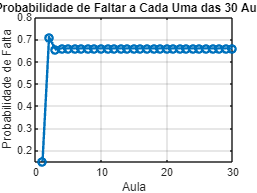

% Matriz de transição
P = [0.70, 0.30;
     0.80, 0.20];

% Vetor de estado inicial (probabilidade de 85% de estar presente na primeira aula)
v = [0.85; 0.15];

% Array para armazenar as probabilidades de faltar a cada uma das 30 aulas
prob_f = zeros(1, 30);

% Inicializar a probabilidade de faltar na primeira aula
prob_f(1) = v(2);

% Aplicar a matriz de transição para cada uma das 30 aulas
for i = 2:30
    v = P * v;
    prob_f(i) = v(2);
end

% Representar graficamente
figure;

plot(1:30, prob_f, '-o', 'LineWidth', 2);
xlabel('Aula');
ylabel('Probabilidade de Falta');
title('Probabilidade de Faltar a Cada Uma das 30 Aulas');

grid on;